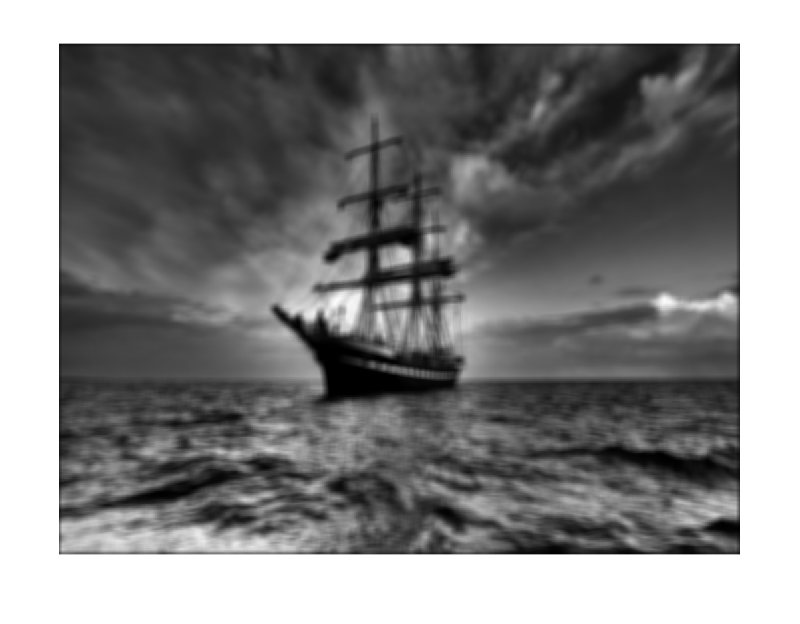

% hw8
img  = imread("../images/greyscale2.jpg");
img = img(:, :, 1);

kernel_x = 12;
kernel_y = 12;
avg3by3 = ones(kernel_x, kernel_y) / (kernel_x * kernel_y);
% Another way: avg3by3 = fspecial('average', [kernel_x, kernel_y])
filtered = filter2(avg3by3, img);
imshow(filtered, [0, 255]);